## Steady state simulation

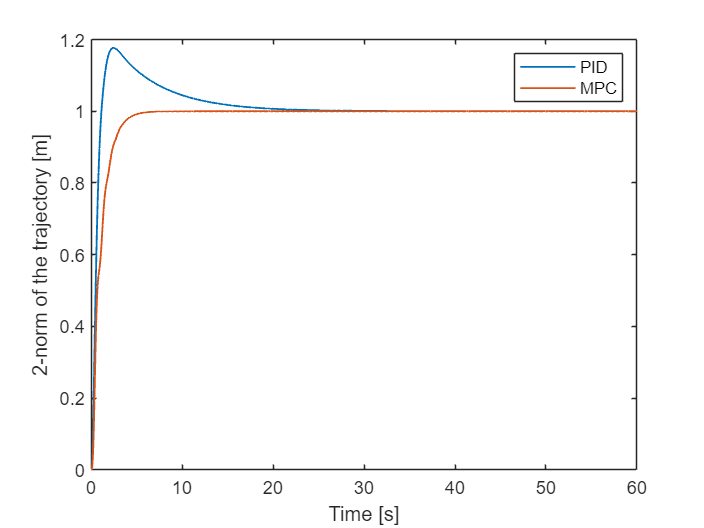

clc
clear
load("Data\PID_Steady_State.mat")
data1 = x;
u1 = u;
load("Data\MPCSteadyState.mat")
data2 = x;
u2 = u;

reference = [0;0;1];
Plot_response(data1,data2,reference,"Accept_Steadystate")

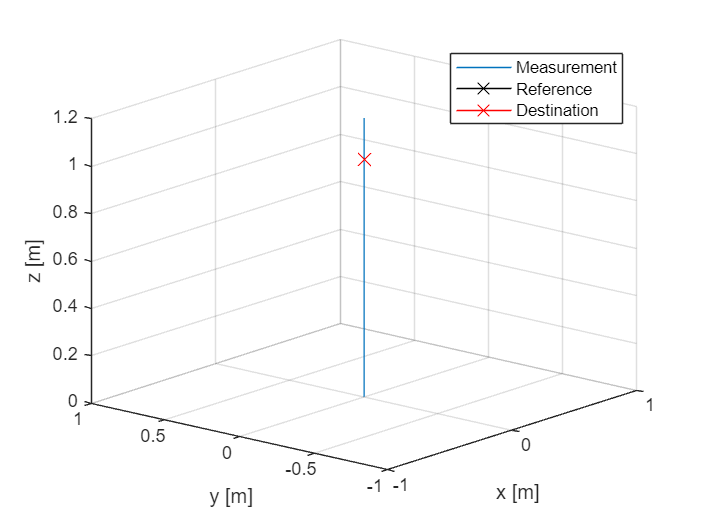

Plot_trajectory(data1,reference,"Accept_PID_Steadystate")

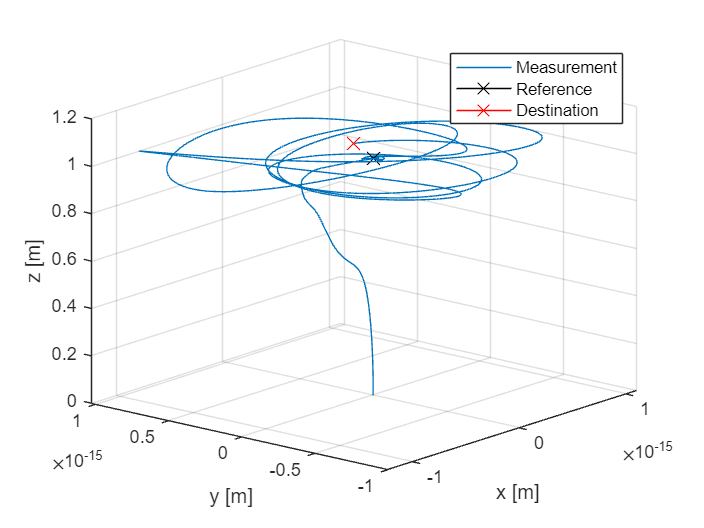

Plot_trajectory(data2,reference,"Accept_MPC_Steadystate")

totalActuation_PID = 2.9277e+03

totalActuation_MPC = 2.9184e+03

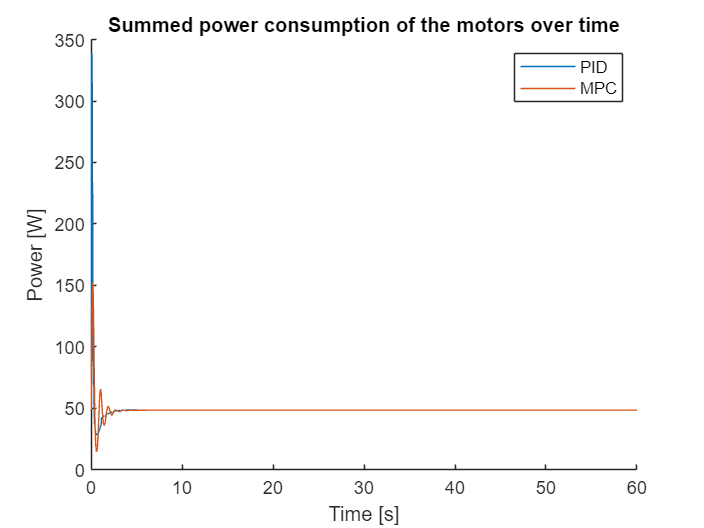

Plot_Actuation(u1,u2,"Accept_Steadystate_Power_Consumption")

## Step response

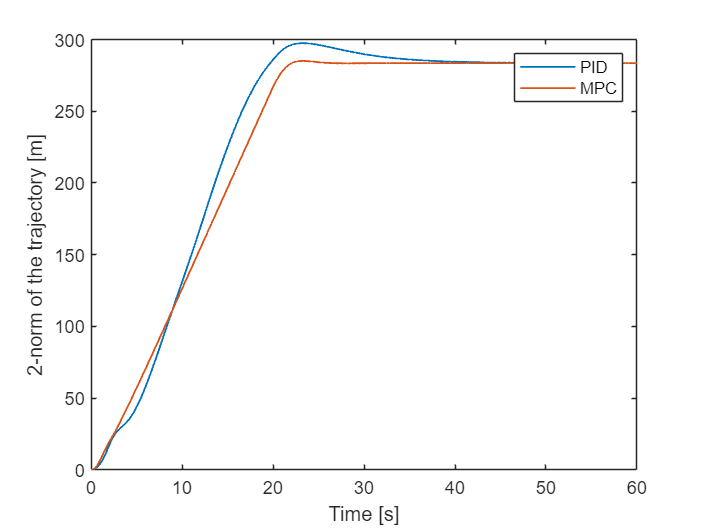

clc
clear
load("Data\PID_Large_step.mat")
data1 = x;
u1 = u;
load("Data\MPCStepResponse.mat")
data2 = x;
u2 = u;

reference = [200;200;20];
Plot_response(data1,data2,reference,"Accept_Step")

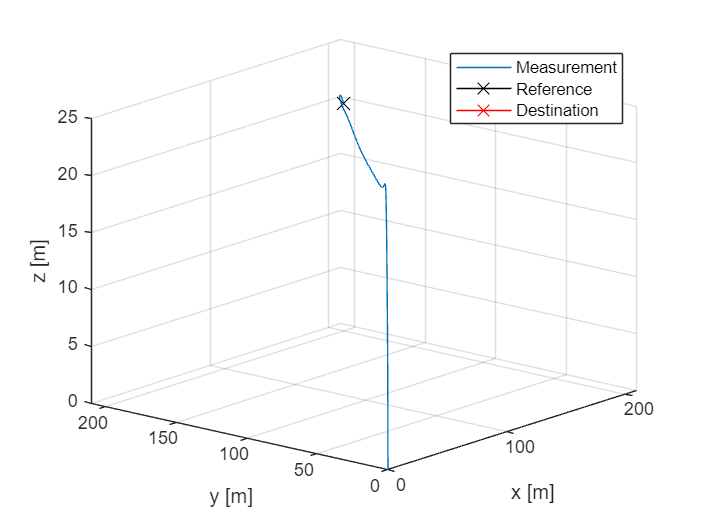

Plot_trajectory(data1,reference,"Accept_PID_Step")

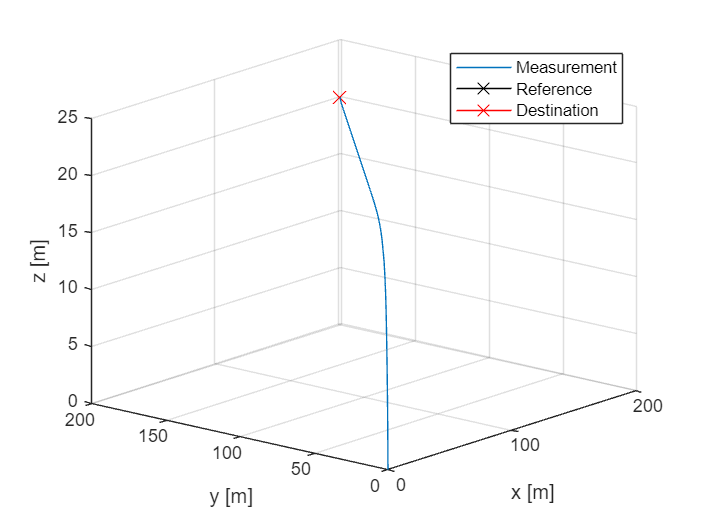

Plot_trajectory(data2,reference,"Accept_MPC_Step")

totalActuation_PID = 3.9232e+03

totalActuation_MPC = 3.5097e+03

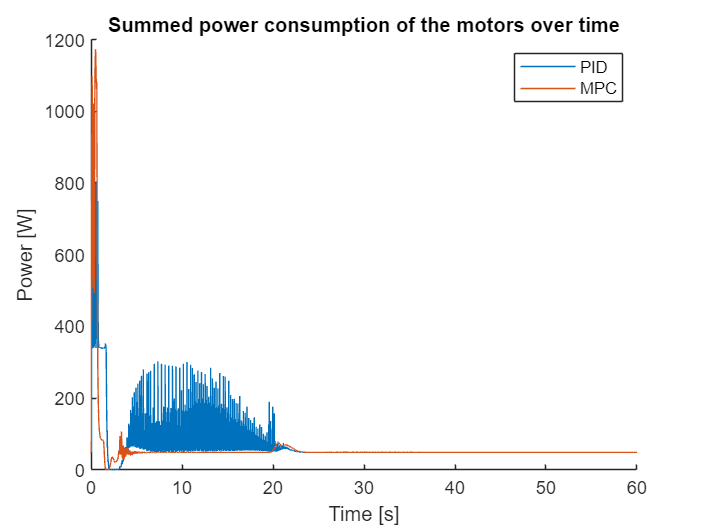

Plot_Actuation(u1,u2,"Accept_Step_Power_Consumption")

## Step response with additional weight

totalActuation_PID = 6.0220e+03

totalActuation_MPC = 5.5622e+03

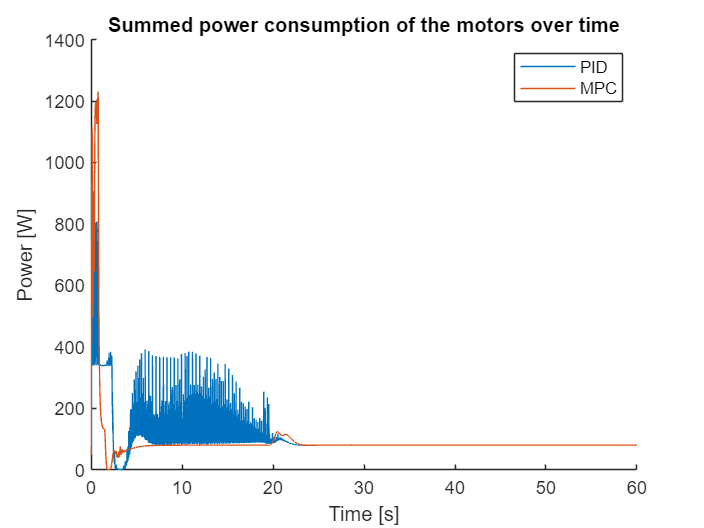

clc
clear
load("Data\PID_Large_step_weight.mat")
data1 = x;
u1 = u;
load("Data\MPCStepResponseWeight.mat")
data2 = x;
u2 = u;

reference = [200;200;20];
% Plot_response(data1,data2,reference,"Accept_Step_Weight")
% Plot_trajectory(data1,reference,"Accept_PID_Step_Weight")
% Plot_trajectory(data2,reference,"Accept_MPC_Step_Weight")
Plot_Actuation(u1,u2,"Accept_Step_Weight_Power_Consumption")


n = size(data1,2);
Ts = 1/800;
t = linspace(0,n*Ts,n);
stepinfo(vecnorm([data1(7,:);data1(8,:);data1(9,:)],2),t,norm(reference),2)

ans = struct with fields:
         RiseTime: 13.2613
    TransientTime: 30.8139
     SettlingTime: 30.8576
      SettlingMin: 255.3951
      SettlingMax: 298.7082
        Overshoot: 5.3842
       Undershoot: 0.7104
             Peak: 296.7082
         PeakTime: 22.6880


stepinfo(vecnorm([data2(7,:);data2(8,:);data2(9,:)],2),t,norm(reference),2)

ans = struct with fields:
         RiseTime: 16.2036
    TransientTime: 20.9114
     SettlingTime: 20.9163
      SettlingMin: 255.4037
      SettlingMax: 285.1014
        Overshoot: 0.5514
       Undershoot: 0.7104
             Peak: 283.1014
         PeakTime: 23.1492


function Plot_response(data1,data2,reference,titleTxt)
    trajectory1 = vecnorm([data1(7,:);data1(8,:);data1(9,:)],2);
    trajectory2 = vecnorm([data2(7,:);data2(8,:);data2(9,:)],2);
    reference = norm(reference,2);

    n = size(trajectory1,2);
    Ts = 1/800;
    t = linspace(0,n*Ts,n);
    
    figure()
    plot(t,trajectory1,t,trajectory2,LineWidth=1)
    % title(titleTxt)
    legend("PID", "MPC")
    ylabel("2-norm of the trajectory [m]")
    xlabel("Time [s]")
    set(gcf, 'PaperUnits', 'centimeters');
    set(gcf, 'PaperPosition', [0 0 16 9]);
    saveas(gcf,strcat('Images/',regexprep(titleTxt, '\s+', '')),'epsc')
end

function Plot_trajectory(x,reference,titleTxt)
    figure()
    hold on
    plot3(x(7,:).',x(8,:).',x(9,:).')
    plot3(reference(1),reference(2),reference(3),Marker="x",Color=[0,0,0],MarkerSize=10)
    plot3(x(7,end),x(8,end),x(9,end),Marker="x",Color=[1,0,0],MarkerSize=10)
    % title("Simulated steady state response")
    xlabel("x [m]")
    ylabel("y [m]")
    zlabel("z [m]")
    legend({'Measurement','Reference','Destination'},"Location","northeast")
    grid on
    hold off
    view([-50 20])
    saveas(gcf,strcat('Images/',regexprep(titleTxt, '\s+', '')),'epsc')
end

function Plot_Actuation(u1, u2, titleTxt)
    g = 9.82;
    m = 1.513;
    kt = 0.011;
    omega_u_lin = m*g/(4*kt);
    Ts = 1/800;
    n = size(u1,2);
    Ts = 1/800;
    t = linspace(0,n*Ts,n);

    summedActuation_PID = sum(2.3536e-07*(u1+omega_u_lin).^3+2.6783e-05*(u1+omega_u_lin).^2);
    summedActuation_MPC = sum(2.3536e-07*(u2+omega_u_lin).^3+2.6783e-05*(u2+omega_u_lin).^2);
    totalActuation_PID = [Ts * ones(1,n)] * summedActuation_PID.'
    totalActuation_MPC = [Ts * ones(1,n)] * summedActuation_MPC.'


    figure()
    hold on
    plot(t,summedActuation_PID,t,summedActuation_MPC)
    hold off
    xlabel("Time [s]")
    ylabel("Power [W]")
    legend("PID","MPC")
    title("Summed power consumption of the motors over time")
    xlim([0 60])
    
    set(gcf, 'PaperUnits', 'centimeters');
    set(gcf, 'PaperPosition', [0 0 16 9]);
    % saveas(gcf,'Images/Accept_Step_Weight_Power_consumption','epsc')
    saveas(gcf,strcat('Images/',regexprep(titleTxt, '\s+', '')),'epsc')
end